# PCB Anomaly Detection Using PatchCore

This live script contains the code from "Detecting Anomalies in MATLAB", which is used to build an anomaly detector for a specific type of printed circuit board. Work through it one section at a time to better understand how to build a PatchCore anomaly detector.

Note that if you do not have a GPU, **do not try training the PatchCore detector**. It will likely take 3 hours or more to train on a CPU. Instead, **use the provided models and results** as you go through the reading.

**Important note: **If you haven't already, you will need to install a few Add-Ons before running this script. See more information on how to do this in [Installing Pre-Trained Models](https://www.coursera.org/learn/advanced-deep-learning-techniques-computer-vision/item/yP3Ml).

## Choose an Anomaly Detection Algorithm

Here, we set up the PatchCore anomaly detector, but there are a variety of anomaly detectors [available in MATLAB](https://www.mathworks.com/help/vision/automated-visual-inspection.html). 

patchcore = patchCoreAnomalyDetector;

## Import and Split the Data

Next, import the printed circuit board images and split them into train, calibration, and test sets, much like the train/validation splits you performed in Courses 1 and 2. Remember that for anomaly detection, we set aside a new set of images (the calibration set) to determine the best anomaly threshold for our data.

% Read in the printed circuit board images located in
% <your course file location>...\Data\Printed Circuit Board
filename = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/Printed Circuit Board";
imds = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames");

% Split the data using the specified ratios for normal and anomalous images
[imdsTrain,imdsCal,imdsTest] = splitAnomalyData(imds,"Anomaly", ...
    NormalLabelsRatio=[0.5,0.1,0.4],AnomalyLabelsRatio=[0,0.2,0.8]);

Splitting anomaly dataset
-------------------------
* Finalizing... Done.
* Number of files and proportions per class in all the datasets:

                      Input                  Train              Validation                Test        
               ____________________    _________________    ___________________    ___________________

               NumFiles     Ratio      NumFiles    Ratio    NumFiles     Ratio     NumFiles     Ratio 
               ________    ________    ________    _____    ________    _______    ________    _______
                                       

## Train or Load in the Detector

This is where you would train the detector, but we've provided a trained model for you in case you don't have the computational resources or time to train your own. If you have a GPU available, feel free to uncomment the first line of code to train your own detector. This model took us about 20 minutes to train on a GPU, but would take a few hours on a CPU. 

Note that you only use the training data to build the anomaly detector. The calibration data will come in at the next step.

load PCBPatchCoreDetector.mat detector
% detector = trainPatchCoreAnomalyDetector(imdsTrain,patchcore);

## Predict Anomaly Scores of Calibration Set

Using the trained model, predict anomaly scores for each image in the calibration set. 

Recall that anomaly detection assigns a score to every pixel in the image. This means predicting anomalies requires significant computational effort for a powerful model like PatchCore. 

Here, it took us over 15 minutes to predict the anomaly scores on the 120 calibration images using a CPU. If you have the time, uncomment the line of code to make your own predictions. Otherwise, you can use the provided `scores` variable.

% Predict the anomaly scores of images in the calibration set
load PCBPatchCoreScores.mat scores
% scores = predict(detector,imdsCal);

## Visualize Anomaly Scores in a Histogram

Now, plot the anomaly scores for the normal and anomalous calibration images in a histogram. 

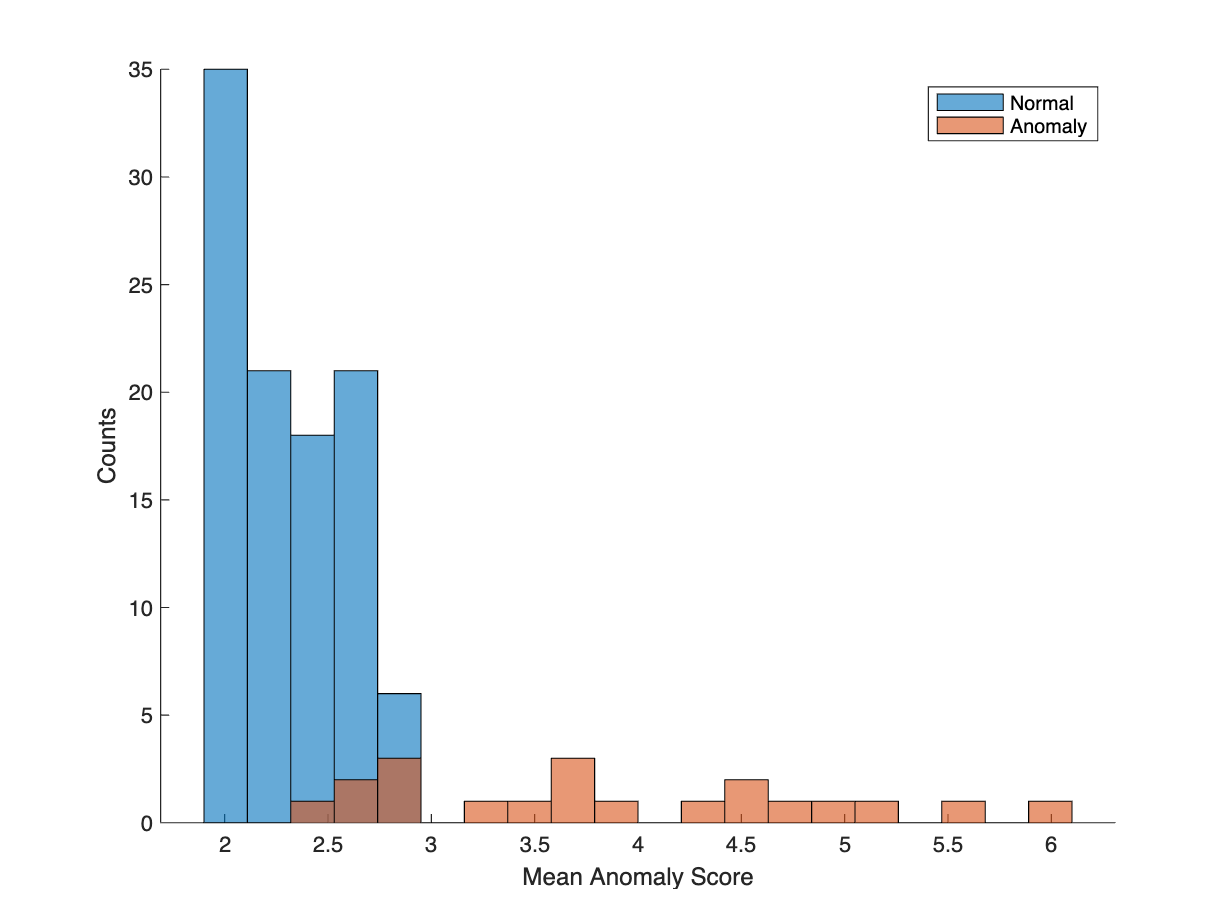

% Get the anomalous image indices
labels = imdsCal.Labels~="Normal";
numBins = 20;

% Save the edge values using the scores and number of bins
%   so the two histograms can be plotted on the same figure
[~,edges] = histcounts(scores,numBins);

figure
hold on

% Plot the histograms using the designated edges
hNormal = histogram(scores(labels==0),edges);
hAnomaly = histogram(scores(labels==1),edges);
hold off

% Add an appropriate legend and axis labels
legend([hNormal,hAnomaly],"Normal","Anomaly")
xlabel("Mean Anomaly Score")
ylabel("Counts")

## Set the Anomaly Threshold

You may choose to manually set the anomaly threshold if, for example, you see a clear separation in the distribution of scores. However, it will usually be difficult to know the best threshold to choose. Use the `anomalyThreshold` function to find an optimal threshold value.

% Select an anomaly threshold 
thresh = anomalyThreshold(labels,scores,true)

thresh = single
2.8000


% Set the anomaly threshold for the detector
detector.Threshold = thresh;

## Evaluate the Model

Finally, classify the test images as normal/anomaly and evaluate the results. This classification step can take 30+ minutes on a CPU, so feel free to use the provided prediction labels in the .mat file instead of running it yourself. 

The `evaluateAnomalyDetection` function outputs a variety of different [metrics](https://www.mathworks.com/help/vision/ref/anomalydetectionmetrics.html#mw_5ea32730-1167-485f-ad12-67bd01e6a984), so when you build your own anomaly detectors, consider which metrics matter most for your application

% Classify the test images
load PCBPatchCorePredLabels.mat testSetPredLabels
% testSetPredLabels = classify(detector,imdsTest);

% Calculate test set accuracy metrics
testSetTrueLabels = imdsTest.Labels;
metrics = evaluateAnomalyDetection(testSetPredLabels,testSetTrueLabels,"Anomaly");

Evaluating anomaly detection results
------------------------------------
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    Precision    Recall    Specificity    F1Score    FalsePositiveRate    FalseNegativeRate
    ______________    ____________    _________    ______    ___________    _______    _________________    _________________

       0.92116           0.9227        0.69811     0.925       0.9204       0.7957         0.079602               0.075      



## Visualize the Confusion Matrix 

You can also use `metrics` from above to visualize the overall results in a confusion matrix. This way, you can see the exact numbers behind the model's accuracy and other metrics.

Randomness during training can produce slightly different results. For the model we trained, 74/80 = 0.925 anomaly images were correctly identified, and 370/402 = 0.920 normal images were correctly identified.

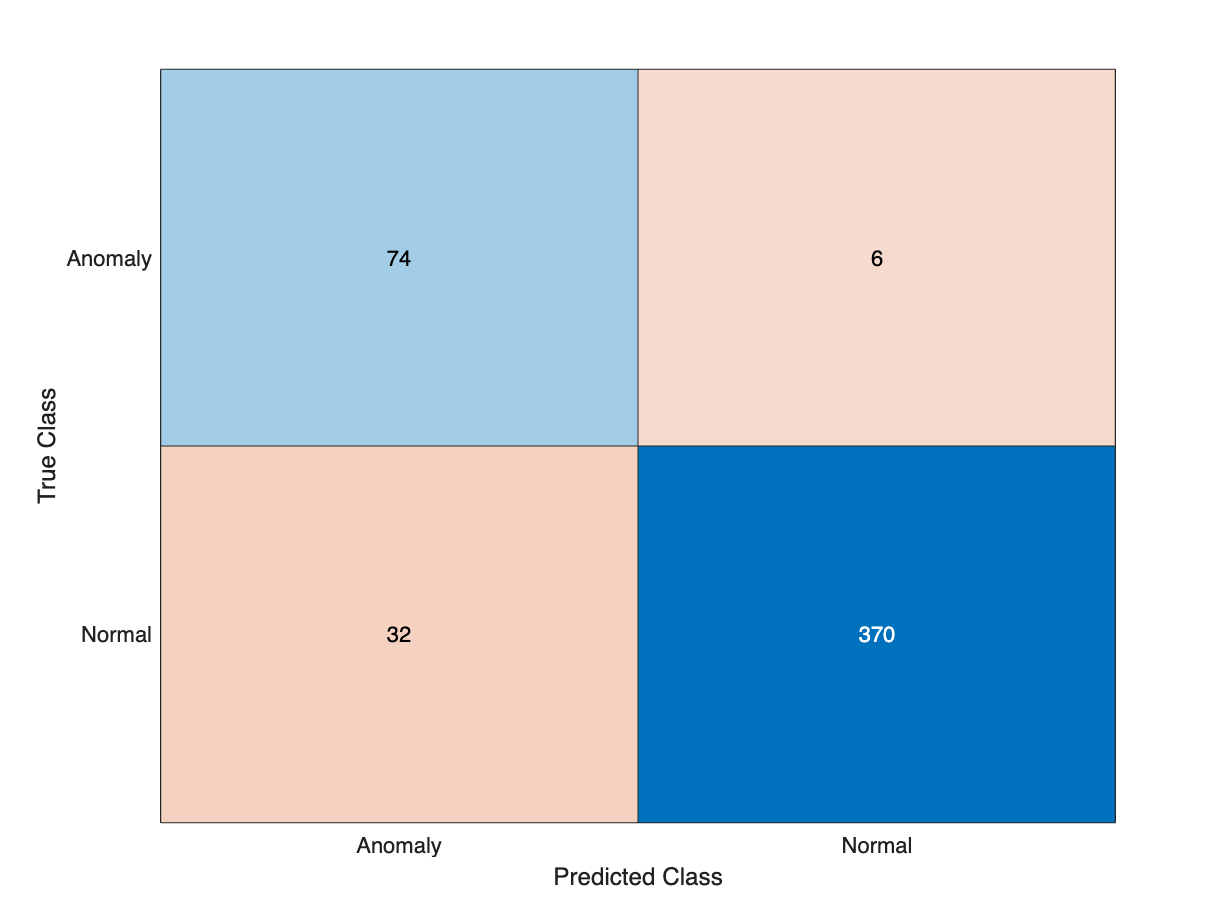

% Display the confusion matrix results
M = metrics.ConfusionMatrix{:,:};
confusionchart(M,["Normal","Anomaly"])

## Visualize the Anomaly Maps

As a final step, you could visualize the anomaly maps-- the color maps of the pixel-level anomaly scores. This can help you better understand the model and identify any anomaly locations if you are not sure where to look.

Note that calculating the anomaly map for each image in the calibration set takes 20+ minutes on a CPU, so uncomment the code below if you want to run it yourself.

% % Find the minimum and maximum anomaly scores in all calibration images
% minMapCal = inf;
% maxMapCal = -inf;
% reset(imdsCal)
% while hasdata(imdsCal)
%     img = read(imdsCal);
%     map = anomalyMap(detector,img);
%     minMapCal = min(min(map,[],"all"),minMapCal);
%     maxMapCal = max(max(map,[],"all"),maxMapCal);
% end
% % Save these values as the display range
% displayRange = [minMapCal,maxMapCal];

load PCBPatchCoreDisplayRange.mat displayRange

% Save the subset of images you want to view anomaly maps for
% Here we focus on the correctly identified anomaly images
testSetAnomalyLabels = testSetTrueLabels' == "Anomaly";
idxTruePositive = find(testSetAnomalyLabels & testSetPredLabels);
dsExample = subset(imdsTest,idxTruePositive);

You can now select any image from the subset specified above to visualize its anomaly map! Note that it will take some time to run on each image.

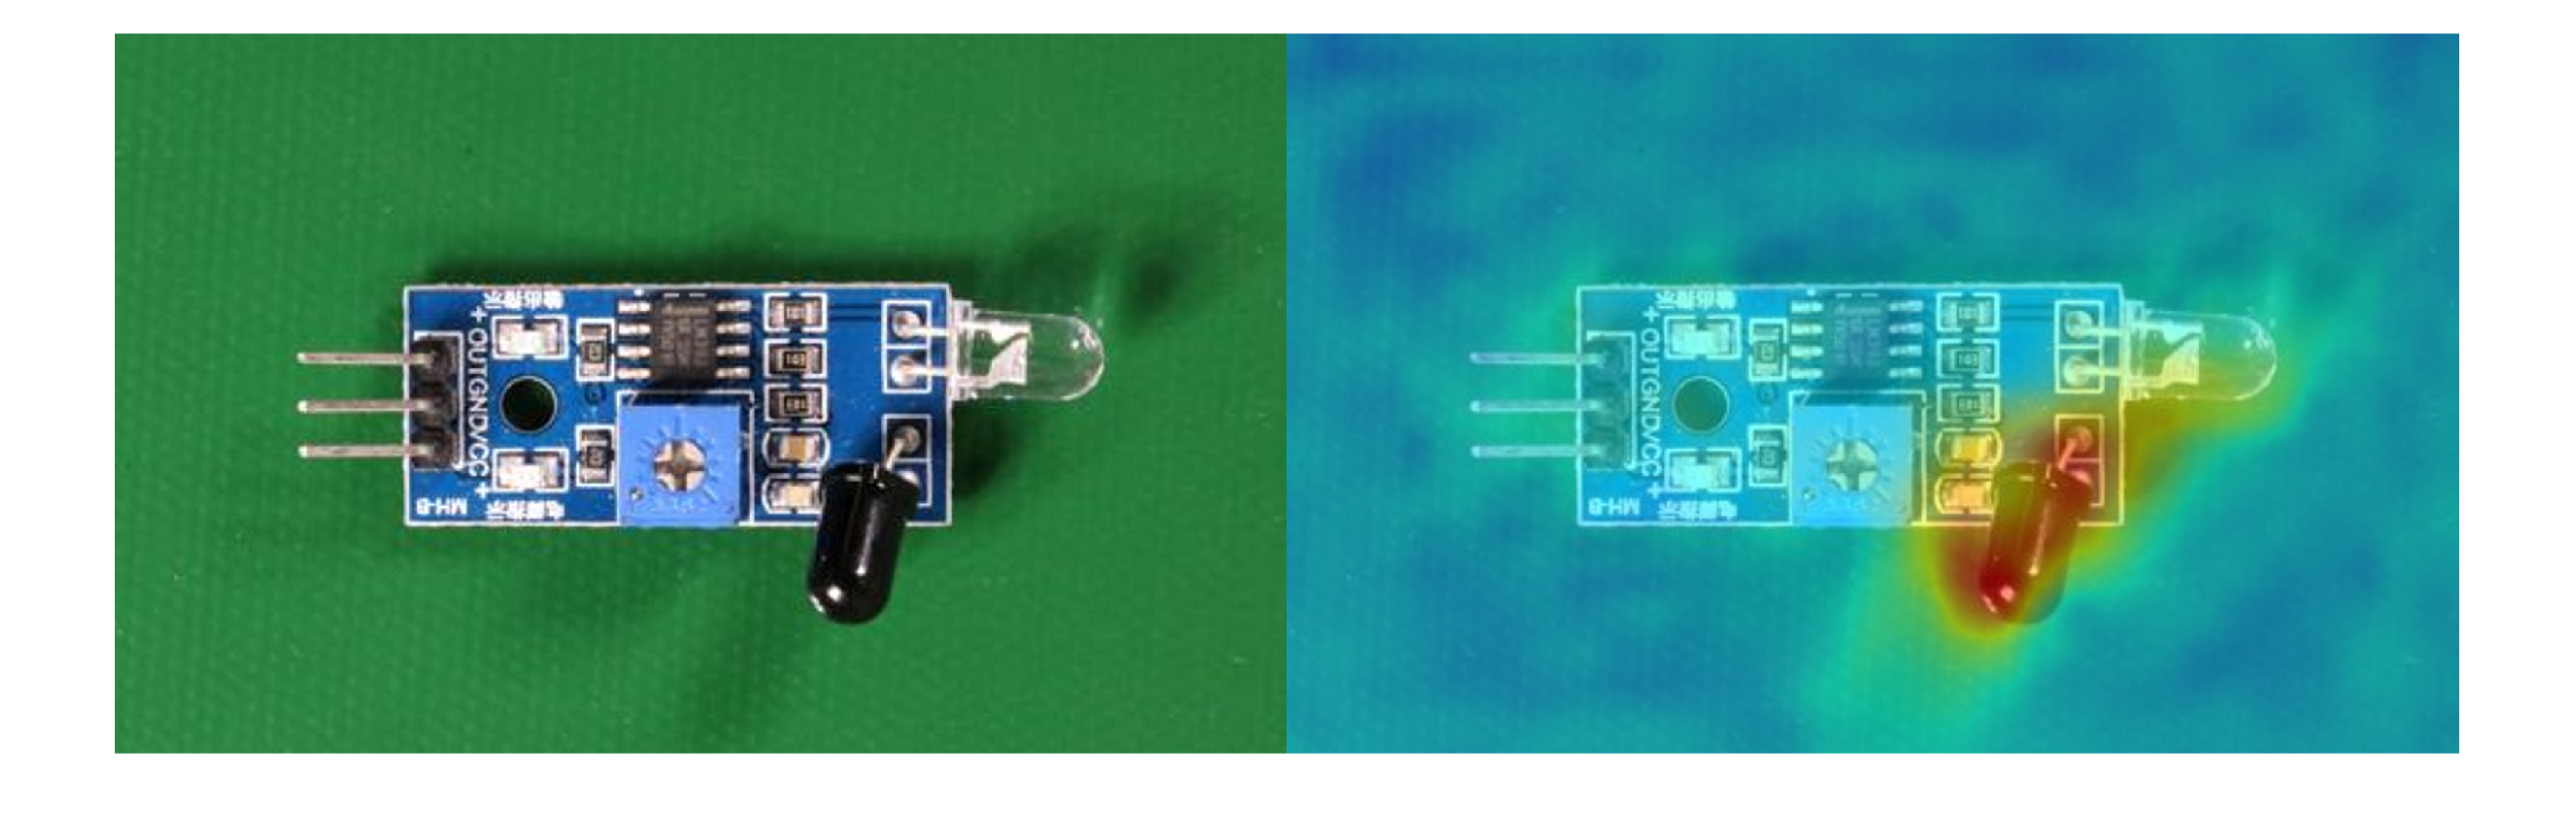

% Select an image from the subset
img = readimage(dsExample,1);

% Calculate the pixel-level anomaly scores
map = anomalyMap(detector,img);

% Visualize the anomaly scores using the display range from earlier
montage({img,anomalyMapOverlay(img,map,"MapRange",displayRange,"Blend","equal")})

*Copyright 2024 The MathWorks, Inc.*